clc
clear
addpath("./support_code/")
Inertia_Moment = 55390782.61*10^-9;
Helicopter_Mass = 2.112;
Applied_Force = 10;

**2D Solution for x and y position**

Now consider that there are two seperate 2D system. one for z/yaw, and the others for pitch and roll. This focuses on pitch and roll. The force F can be vectored by angle theta. However, note that we are only controlling the accelleration/torque on the system, not the exact value, thus the new system needs to be defined for this (below)

Note that **you need to take the sine of theta**, because the angle from the vertical is cos(pi-theta) = sin(theta)

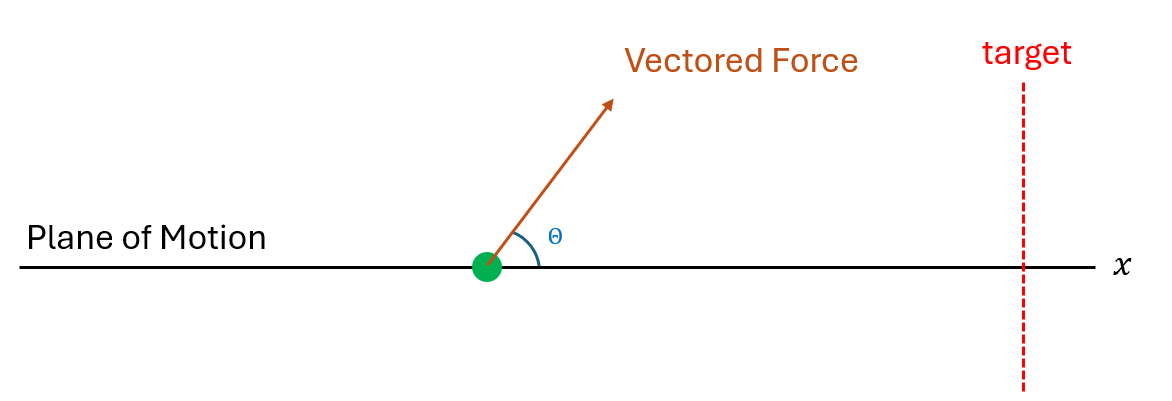

**DOF:       **[x , theta]

**INPUTS: **[Torque] <- Force is not an input, the helicopter applies the amount of force exactly required to maintain altitude. Thus force is a function of state,

Therefore:

**States  : **[x, dx, theta, dtheta ]

syms t 
syms s(t) theta(t)
syms x [4 1] 

assume(t, 'real')
assume(s(t), 'real')
assume(theta(t), 'real')

ds = diff(s(t), t);
dds = diff(ds, t);
dtheta = diff(theta(t), t);
ddtheta = diff(dtheta, t);


x = [s(t); ds; theta(t); dtheta];
dx = diff(x, t)

$$dx = \left(\begin{array}{c} \frac{\partial }{\partial t}s\left(t\right)\\ \frac{\partial^{2}}{\partial t^{2}}s\left(t\right)\\ \frac{\partial }{\partial t}\theta \left(t\right)\\ \frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right) \end{array}\right)$$

toLatex(x, "AD/1D/state", true)
toLatex(dx, "AD/1D/dstate", true)


OK now that everything is set up, now to create the function f(x,u), where x is the state, and u is the torque and force.

The force is just f = ma, and torque uses I where I is the moment in that direction.

syms m I T real
syms F(t)
assume(F(t), 'positive')
assume(F(t), 'real')

eq1 = x(2);
eq2 = (F / m) * sin( x(3) );
eq3 = x(4);
eq4 = T / I;


f_x_u = [eq1 ; eq2 ; eq3 ; eq4]

$$f\_x\_u(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}s\left(t\right)\\ \frac{\sin\left(\theta \left(t\right)\right)\,F\left(t\right)}{m}\\ \frac{\partial }{\partial t}\theta \left(t\right)\\ \frac{T}{\text{I}} \end{array}\right)$$

Now we need a system that must converge to zero, so we use the error function in order to derrive a Lyupanov function as well as backstepping.

Error -> Lyupanov

syms x_t real
target = [x_t ; 0 ; 0 ; 0];
toLatex(f_x_u, "AD/1D/test", true)
e = target - x

$$e = \left(\begin{array}{c} x_{t}-s\left(t\right)\\ -\frac{\partial }{\partial t}s\left(t\right)\\ -\theta \left(t\right)\\ -\frac{\partial }{\partial t}\theta \left(t\right) \end{array}\right)$$

toLatex(e, "AD/1D/error", true)

Lyupanov Function and Derrivative

syms V(x)

V(x) = 0.5 * e'*e

$$V(x) = \frac{\bar{\frac{\partial }{\partial t}s\left(t\right)}\,\frac{\partial }{\partial t}s\left(t\right)}{2}+\frac{\bar{\frac{\partial }{\partial t}\theta \left(t\right)}\,\frac{\partial }{\partial t}\theta \left(t\right)}{2}+\left(x_{t}-s\left(t\right)\right)\,\left(\frac{x_{t}}{2}-\frac{\bar{s\left(t\right)}}{2}\right)+\frac{\bar{\theta \left(t\right)}\,\theta \left(t\right)}{2}$$

dV = simplify(subs(diff(V(x), t), dx', f_x_u'))

$$dV = \begin{array}{l} \frac{\sigma_{2}\,\theta \left(t\right)}{2}+\frac{\bar{\theta \left(t\right)}\,\frac{\partial }{\partial t}\theta \left(t\right)}{2}-\frac{\sigma_{1}\,\left(x_{t}-s\left(t\right)\right)}{2}+\frac{\sigma_{1}\,\frac{\partial^{2}}{\partial t^{2}}s\left(t\right)}{2}+\frac{\sigma_{2}\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)}{2}-\left(\frac{x_{t}}{2}-\frac{\bar{s\left(t\right)}}{2}\right)\,\frac{\partial }{\partial t}s\left(t\right)+\frac{T\,\frac{\partial }{\partial t}\theta \left(t\right)}{2\,\text{I}}+\frac{F\left(t\right)\,\sin\left(\bar{\theta \left(t\right)}\right)\,\frac{\partial }{\partial t}s\left(t\right)}{2\,m}\\ \mathrm{where}\\ \sigma_{1}=\bar{\frac{\partial }{\partial t}s\left(t\right)}\\ \sigma_{2}=\bar{\frac{\partial }{\partial t}\theta \left(t\right)} \end{array}$$

toLatex(V(x), "AD/1D/lyupanov", false)
toLatex(dV, "AD/1D/dlyupanov", false)

Knowing that T is the only input, and \dot V needs to be strictly < 0 for all values, we choose u=[T] that satisfies this condition

syms k1 k2 positive real
Vdot_desired_bad = -k1*s^2 - k2*dtheta^2

$$Vdot\_desired\_bad(t) = -k_{2}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}-k_{1}\,{s\left(t\right)}^{2}$$

toLatex(Vdot_desired_bad, "AD/1D/dV_desired", false)

Solve the solution that satisfies this equation

T_sol_bad = simplify(solve(dV == Vdot_desired_bad, T))

$$T\_sol\_bad = \begin{array}{l} -\frac{2\,\text{I}\,\left(k_{1}\,{s\left(t\right)}^{2}+\frac{\sigma_{2}\,\theta \left(t\right)}{2}+\frac{\bar{\theta \left(t\right)}\,\frac{\partial }{\partial t}\theta \left(t\right)}{2}-\frac{\sigma_{1}\,\left(x_{t}-s\left(t\right)\right)}{2}+\frac{\sigma_{1}\,\frac{\partial^{2}}{\partial t^{2}}s\left(t\right)}{2}+\frac{\sigma_{2}\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)}{2}+k_{2}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}-\left(\frac{x_{t}}{2}-\frac{\bar{s\left(t\right)}}{2}\right)\,\frac{\partial }{\partial t}s\left(t\right)+\frac{F\left(t\right)\,\sin\left(\bar{\theta \left(t\right)}\right)\,\frac{\partial }{\partial t}s\left(t\right)}{2\,m}\right)}{\frac{\partial }{\partial t}\theta \left(t\right)}\\ \mathrm{where}\\ \sigma_{1}=\bar{\frac{\partial }{\partial t}s\left(t\right)}\\ \sigma_{2}=\bar{\frac{\partial }{\partial t}\theta \left(t\right)} \end{array}$$

toLatex(T_sol_bad, "AD/1D/reqired_torq_bad", false)

The above works, but the denominator term creates a very unstable mode, thus we need to redesingn the lyupanov function such that this problem does not arise.Direct Lyupanov function does not work here

**Backstepping**

Break into two subsystems so that backstepping can be used


%Define the two subsystems
x_1 = [ s(t) ; ds ];
x_2 = [ theta ; dtheta ];
 
f_1 = f_x_u(1:2);
f_2 = f_x_u(3:4);


toLatex(x_1, "AD/1D/subsystem_1", true)
toLatex(x_2, "AD/1D/subsystem_2", true)
% toLatex(f_1, "AD/1D/f_x_1", true) %Better one below
% toLatex(f_2, "AD/1D/f_x_2", true) %Better one below

Now To do the backstepping with the first subsystem, we do the direct lyupanov approach for each of them with a target position and a target angle.

syms theta_t(t) % the(t) is the input of theta, becasue the setpoint will be constant, but the target angle will change
omega = diff(theta,t); % angular rate


%error functions
e1 = theta - theta_t;

%Virtual control
alpha = diff(theta_t,t) - k1*e1;
e2 = omega - alpha;

toLatex(e1, "AD/1D/error_1", false)
toLatex(e2, "AD/1D/error_2", false)


Two different lyupanov functions for the 2 steps of backstepping

V1 = 1/2*e1^2;
V2 = V1 + 1/2*e2^2;

toLatex(V1, "AD/1D/V1", false)
toLatex(V2, "AD/1D/V2", false)

dV2 = diff(V2,t);

Subsitude state update function into the lyupanov function

dV2 = subs(dV2, diff(omega, t), T/I)

$$dV2(t) = \left(\frac{\partial }{\partial t}\theta \left(t\right)-\frac{\partial }{\partial t}\theta_{t}\left(t\right)\right)\,\left(\theta \left(t\right)-\theta_{t}\left(t\right)\right)+\left(k_{1}\,\left(\frac{\partial }{\partial t}\theta \left(t\right)-\frac{\partial }{\partial t}\theta_{t}\left(t\right)\right)+\frac{T}{\text{I}}-\frac{\partial^{2}}{\partial t^{2}}\theta_{t}\left(t\right)\right)\,\left(k_{1}\,\left(\theta \left(t\right)-\theta_{t}\left(t\right)\right)+\frac{\partial }{\partial t}\theta \left(t\right)-\frac{\partial }{\partial t}\theta_{t}\left(t\right)\right)$$

toLatex(dV2, "AD/1D/dV2", false)

Choose a target negative definate Lyupanov Function derrivative

Target = -k1*e1^2 - k2*e2^2;
toLatex(Target, "AD/1D/target_dv2", false)
T_sol = (simplify( solve( dV2 == Target , T ) ))

$$T\_sol = \text{I}\,\theta_{t}\left(t\right)-\text{I}\,\theta \left(t\right)+\text{I}\,\frac{\partial^{2}}{\partial t^{2}}\theta_{t}\left(t\right)-\text{I}\,k_{1}\,\frac{\partial }{\partial t}\theta \left(t\right)-\text{I}\,k_{2}\,\frac{\partial }{\partial t}\theta \left(t\right)+\text{I}\,k_{1}\,\frac{\partial }{\partial t}\theta_{t}\left(t\right)+\text{I}\,k_{2}\,\frac{\partial }{\partial t}\theta_{t}\left(t\right)-\text{I}\,k_{1}\,k_{2}\,\theta \left(t\right)+\text{I}\,k_{1}\,k_{2}\,\theta_{t}\left(t\right)$$

toLatex(T_sol, "AD/1D/Torque_Solution", false)

Quick Simulation Check


I_val  = Inertia_Moment;
k1_inner = 50;
k2_inner = 20;

theta_ref   = @(t) 0.3*sin(2*t);
dtheta_ref  = @(t) 0.6*cos(2*t);
ddtheta_ref = @(t)-1.2*sin(2*t);


syms t theta_sym dtheta_sym real

T_num = subs(T_sol, {k1,k2,I}, {k1_inner,k2_inner,I_val});

T_num = subs(T_num, ...
             {theta_t(t),  diff(theta_t(t),t),  diff(theta_t(t),t,2)}, ...
             {theta_ref(t), dtheta_ref(t),      ddtheta_ref(t)});

T_num = subs(T_num, {theta(t), diff(theta(t),t)}, {theta_sym, dtheta_sym});

% build fast numeric evaluator --------------------------------------
Tfun  = matlabFunction(T_num, 'Vars', [t, theta_sym, dtheta_sym]);


rhs = @(t,x) [ x(2) ; Tfun(t,x(1),x(2))/I_val ];


tspan = [0 10];           % 10-s run
x0    = [0; 0];           % initial θ, θ̇
[t,x] = ode45(rhs, tspan, x0);

theta  = x(:,1);
omega  = x(:,2);

%% 5.  plots ----------------------------------------------------------
figure(1); clf;
subplot(3,1,1)
plot(t, theta, '-', t, theta_ref(t), '--', 'LineWidth',1.3);
grid on;  xlabel('time [s]'); ylabel('\theta [rad]');
legend('\theta(t)','\theta_t(t)','Location','SouthWest');
title('Back-stepping attitude tracking');

subplot(3,1,2)
plot(t, theta - theta_ref(t), 'LineWidth',1.3);
grid on; xlabel('time [s]'); ylabel('e_1 [rad]');
title('tracking error  e_1');

subplot(3,1,3)
Tlog = arrayfun(@(tt,th,om) Tfun(tt,th,om), t, theta, omega);
plot(t, Tlog, 'LineWidth',1.3);
grid on; xlabel('time [s]'); ylabel('T [N·m]');
title('control torque')



if false
   
    
    %% —————— 3) Run the optimizer ——————
    K0   = [30; 12];           % initial [k1; k2]
    opts = optimset( ...
        'Display',      'iter', ...        % still print progress
        'TolX',         1e-2,   ...        % stop when ΔK < 0.01
        'TolFun',       1e-2,   ...        % stop when ΔJ < 0.01
        'MaxIter',      25,    ...        % at most 200 iterations
        'MaxFunEvals',  25         ...    % at most 500 cost calls
    );
    
    [K_opt, J_opt] = fminsearch(@cost, K0, opts);
    K_opt(1)
    K_opt(2)



    
end
function J = cost(K)

    I_val       = 55390782.61e-9;
    theta_ref   = @(t) 0.3*sin(2*t);
    dtheta_ref  = @(t) 0.6*cos(2*t);
    ddtheta_ref = @(t)-1.2*sin(2*t);

    k1 = K(1);
    k2 = K(2);

    tspan = [0 10];
    x0    = [0;0];

    % your PD+feedforward law
    Tfun = @(t,theta,dtheta) ...
              I_val*ddtheta_ref(t) ...
            + k1*(theta_ref(t) - theta) ...
            + k2*(dtheta_ref(t)-dtheta);

    rhs = @(t,x)[ x(2);
                  Tfun(t,x(1),x(2))/I_val ];
    [tt,xx] = ode45(rhs, tspan, x0);

    theta_sim = xx(:,1);
    e = theta_sim - theta_ref(tt);

    % sample the torque at the same time points
    Tvec = arrayfun(@(ti,th,td) Tfun(ti,th,td), tt, xx(:,1), xx(:,2));


    % 1) tracking error (sum-squared)
    J_err = sum(e.^2);
    J_u2  = sum(Tvec.^2);

    % final cost
    J = J_err + J_u2;
end


The same but for S

syms s_d real
e1   = s - s_d;
e2   = ds;
ddes = -k1*e1 - k2*e2;

f1 = [ ds; (F/m)*sin(theta) ];
toLatex(f1, "AD/1D/f_x_1", true)

sin_theta = simplify( (m/F)*ddes );

toLatex(sin(theta) == sin_theta, "AD/1D/sin_theta", false)

theta_ctrl = simplify( asin(sin_theta) )

$$theta\_ctrl(t) = -\mathrm{asin}\left(\frac{m\,\left(k_{2}\,\frac{\partial }{\partial t}s\left(t\right)-k_{1}\,\left(s_{d}-s\left(t\right)\right)\right)}{F\left(t\right)}\right)$$


%% ———————— result: control law θ = θ_ctrl(s,ds) ————————
u = theta_ctrl

$$u(t) = -\mathrm{asin}\left(\frac{m\,\left(k_{2}\,\frac{\partial }{\partial t}s\left(t\right)-k_{1}\,\left(s_{d}-s\left(t\right)\right)\right)}{F\left(t\right)}\right)$$

toLatex(u, "AD/1D/displacement_input", false)


%% ———————— Build the closed-loop ODE as a function of x = [s; ds] ————————
syms m F k1 k2 s_d real             % parameters
syms t                             % (unused) time symbol

% pack s and ds into a single symbolic vector
syms x [2 1] real                  
s  = x(1);                         
ds = x(2);                        

sin_theta = (m/F)*(-k1*(s - s_d) - k2*ds);
toLatex(sin(theta) == sin_theta, "AD/1D/sin_theta_expanded", false)

% closed‐loop dynamics f_cl(x):
f_cl = [ ds; (F/m)*sin_theta ]

$$f\_cl = \left(\begin{array}{c} x_{2}\\ k_{1}\,\left(s_{d}-x_{1}\right)-k_{2}\,x_{2} \end{array}\right)$$

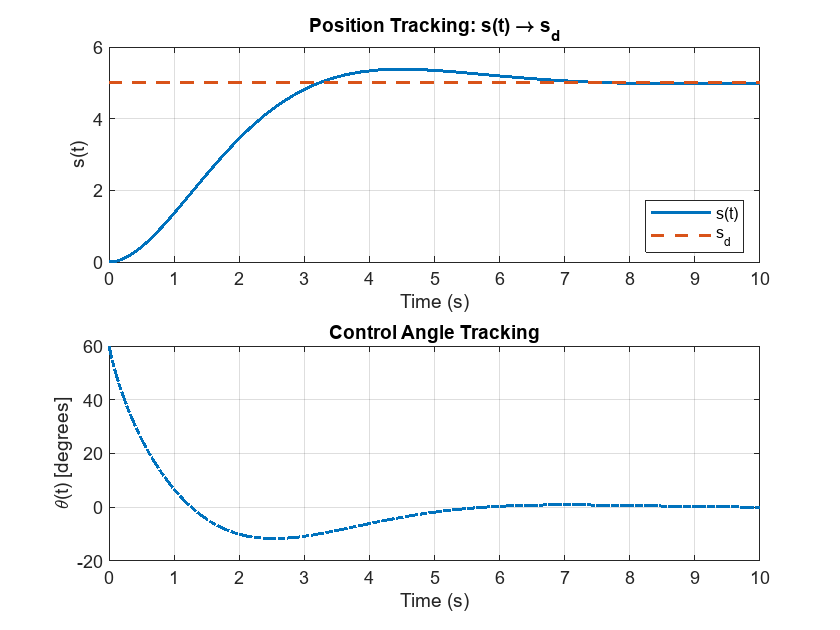

toLatex(f_cl, "AD/1D/closed_loop_displacement", true)


% now generate a MATLAB function handle
f_num = matlabFunction( f_cl, ...
                        'Vars', { t,    ... % scalar time
                                  x,    ... % 2×1 state vector
                                  m, F, k1, k2, s_d } );

%% ———————— Numerical sim with ode45 ————————
% choose numeric values: k1 = 1.1616, k2 = 3.3154
m_val   = Helicopter_Mass;
F_val   = Applied_Force;
k1_outer  = 0.8199;
k2_outer  = 1.1483;
s_d_val = 5;

% pack into ode45‐style function
odefun = @(t,x) f_num(t, x, m_val, F_val, k1_outer, k2_outer, s_d_val);

% simulate from rest toward s_d
tspan = [0,10];
x0    = [0; 0];
[t_sol, X] = ode45(odefun, tspan, x0);

%% ———————— Compute θ(t) from the simulated states ————————
sin_theta_num = (m_val/F_val)*(-k1_outer*(X(:,1) - s_d_val) - k2_outer*X(:,2));
sin_theta_num = max(min(sin_theta_num,1),-1);   % clip into [-1,1]
theta_deg     = rad2deg(asin(sin_theta_num));  % convert to degrees

%% ———————— Combined Figure with 2 Subplots ————————
figure;

% Subplot 1: Position tracking
subplot(2,1,1);
plot(t_sol, X(:,1), 'LineWidth',1.5); hold on;
plot(tspan, s_d_val*[1 1], '--','LineWidth',1.5);
xlabel('Time (s)');
ylabel('s(t)');
title('Position Tracking: s(t) \rightarrow s_d');
legend('s(t)','s_d','Location','Best');
grid on;

% Subplot 2: Control angle θ(t)
subplot(2,1,2);
plot(t_sol, theta_deg, '-.', 'LineWidth',1.5);
xlabel('Time (s)');
ylabel('\theta(t) [degrees]');
title('Control Angle Tracking');
grid on;

Optimize

if false
    % Constants
    m_val   = Helicopter_Mass;
    F_val   = Applied_Force;
    s_d_val = 5;
    
    % Time span and initial state
    tspan = [0, 10];
    x0 = [0; 0];
    
    % Cost function to minimize
    new_cost = @(K) simulate_cost(K, m_val, F_val, s_d_val, x0, tspan);
    
    % Initial guess for gains
    K0 = [10; 10];
    
    % Optimization options
    opts = optimset('Display','iter','TolX',1e-2,'TolFun',1e-2,'MaxIter',30);
    
    % Run optimizer
    [K_opt, J_opt] = fminsearch(new_cost, K0, opts);
    fprintf('Optimal gains: k1 = %.4f, k2 = %.4f\n', K_opt(1), K_opt(2));
end



function J = simulate_cost(K, m_val, F_val, s_d_val, x0, tspan)
    k1_val = K(1);
    k2_val = K(2);

    % Define ODE system
    f_num = @(t,x) [x(2);
                    (F_val/m_val) * (m_val/F_val) * (-k1_val*(x(1)-s_d_val) - k2_val*x(2))];
    
    [t_sol, X] = ode45(f_num, tspan, x0);

    % Calculate theta from cos(theta)
    cos_theta = (m_val/F_val)*(-k1_val*(X(:,1) - s_d_val) - k2_val*X(:,2));
    cos_theta = max(min(cos_theta,1),-1);
    theta_deg = acos(cos_theta) * (180/pi);

    % Cost: 1) RMS tracking error, 2) overshoot penalty, 3) angle penalty
    err = X(:,1) - s_d_val;
    overshoot = max(X(:,1) - s_d_val, 0);
    angle_penalty = max(abs(theta_deg) - 30, 0);  % degrees beyond 30

    % Weighted sum of penalties
    J = mean(err.^2) + 10*mean(overshoot.^2) + 100*mean(angle_penalty.^2);
end

syms m F k1 k2 s_d real
syms t
syms x [2 1] real

s  = x(1);  ds = x(2);
sin_theta = (m/F)*(-k1*(s - s_d) - k2*ds);
f_cl = [ ds;
         (F/m)*sin_theta ];
f_num = matlabFunction(f_cl, 'Vars', {t, x, m, F, k1, k2, s_d})

f_num = function_handle with value:
    @(t,in2,m,F,k1,k2,s_d)[in2(2,:);-k2.*in2(2,:)+k1.*(s_d-in2(1,:))]


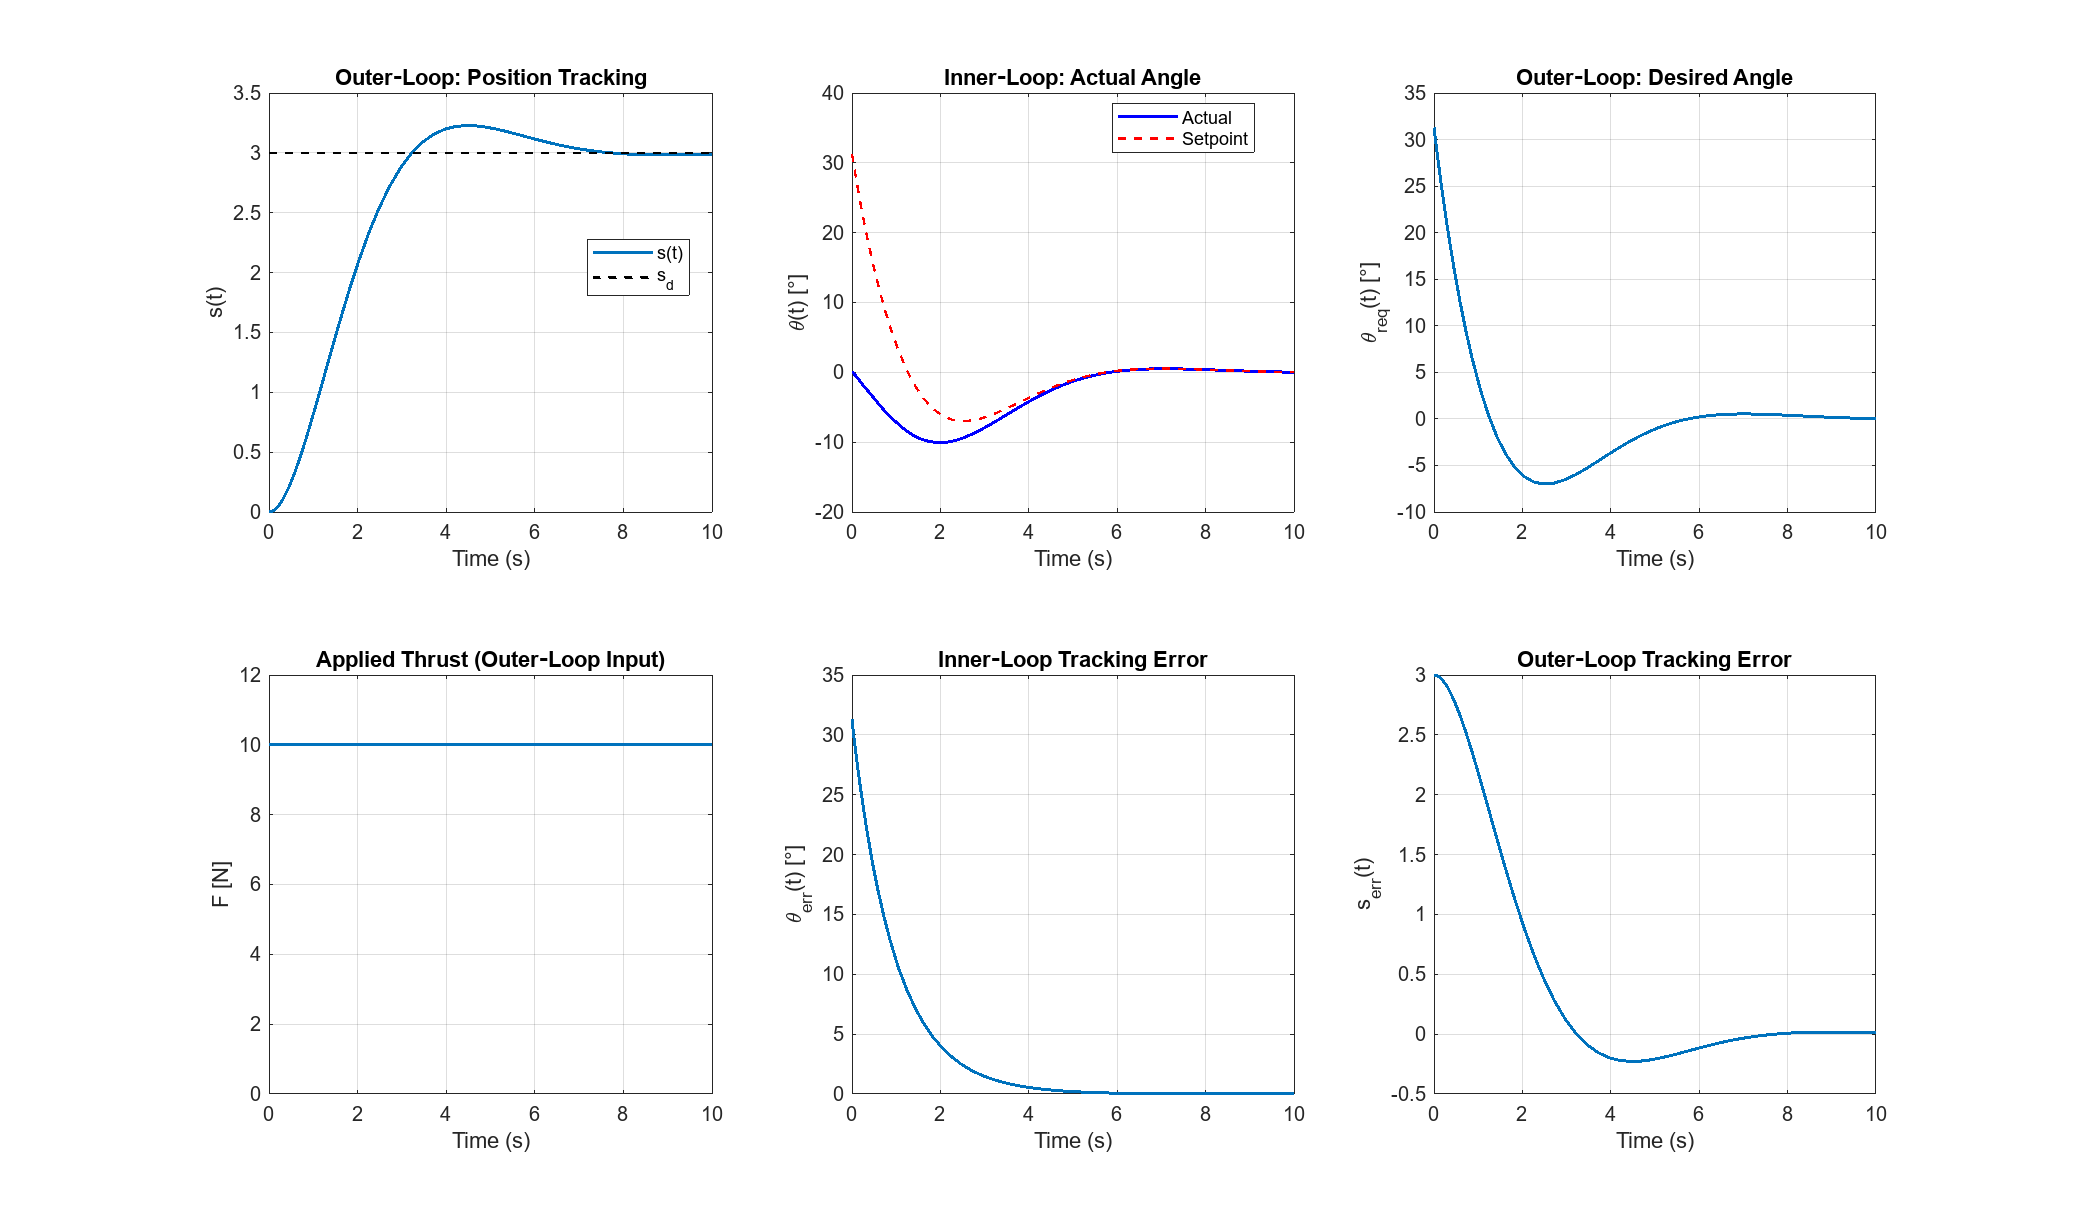



% ALL CONSTANTS
m_val   = 2.112;   
F_val   = Applied_Force;
I_val   = Inertia_Moment;
s_d_val = 3;

k1_val  = k1_outer; 
k2_val  = k2_outer;
k1_i    = k1_inner;
k2_i    = k1_inner;





odefun = @(t,x) f_num(t, x, m_val, F_val, k1_val, k2_val, s_d_val);
tspan  = [0 10]; x0 = [0;0];
[t_out, X_out] = ode45(odefun, tspan, x0);

sin_theta_num   = (m_val/F_val)*(-k1_val*(X_out(:,1)-s_d_val) - k2_val*X_out(:,2));
sin_theta_num   = max(min(sin_theta_num,1),-1);
theta_req_rad   = asin(sin_theta_num);
theta_req_fun   = @(tq) interp1(t_out, theta_req_rad, tq, 'pchip');

dtheta_req      = gradient(theta_req_rad, t_out);
dtheta_req_fun  = @(tq) interp1(t_out, dtheta_req, tq, 'pchip');
ddtheta_req     = gradient(dtheta_req, t_out);
ddtheta_req_fun = @(tq) interp1(t_out, ddtheta_req, tq, 'pchip');

T_ctrl = @(t, th, om) ...
    I_val * ( ddtheta_req_fun(t) ...
            + k1_i*( theta_req_fun(t) - th ) ...
            + k2_i*( dtheta_req_fun(t) - om ) );


rhs_i = @(t,x) [ x(2);
                 T_ctrl(t, x(1), x(2)) / I_val ];

[t_in, X_in] = ode45(rhs_i, tspan, [0; 0]);
theta_in = X_in(:,1);


% Convert to degrees
theta_in_deg  = rad2deg(theta_in);
theta_req_deg = rad2deg(theta_req_rad);

% Tracking errors
theta_err_deg = theta_req_deg - interp1(t_in, theta_in_deg, t_out, 'pchip', 0);
s_err = s_d_val - X_out(:,1);

% PLOTTING
figure('Units','normalized','Position',[0.05 0.1 0.9 0.8]);

% 1) Outer-loop: Position Tracking
subplot(2,3,1);
plot(t_out, X_out(:,1), 'LineWidth',1.5); hold on;
plot(tspan, s_d_val*[1 1], 'k--','LineWidth',1.2);
xlabel('Time (s)'); ylabel('s(t)');
title('Outer‐Loop: Position Tracking');
legend('s(t)','s_d','Location','Best');
grid on;

% 2) Inner-loop: Actual Angle
subplot(2,3,2);
plot(t_in, theta_in_deg, 'b', 'LineWidth',1.5); hold on;
plot(t_out, theta_req_deg, 'r--', 'LineWidth',1.2);  % Setpoint
xlabel('Time (s)'); ylabel('\theta(t) [°]');
title('Inner‐Loop: Actual Angle');
legend('Actual','Setpoint','Location','Best');
grid on;

% 3) Outer-loop: θ_req(t)
subplot(2,3,3);
plot(t_out, theta_req_deg, 'LineWidth',1.5);
xlabel('Time (s)'); ylabel('\theta_{req}(t) [°]');
title('Outer‐Loop: Desired Angle');
grid on;

% 4) Applied Force F (Outer-loop input)
subplot(2,3,4);
plot(t_out, F_val*ones(size(t_out)), 'LineWidth',1.5);
xlabel('Time (s)'); ylabel('F [N]');
title('Applied Thrust (Outer‐Loop Input)');
ylim([0 1.2*F_val]);
grid on;

% 5) Inner-loop Tracking Error
subplot(2,3,5);
plot(t_out, theta_err_deg, 'LineWidth',1.5);
xlabel('Time (s)'); ylabel('\theta_{err}(t) [°]');
title('Inner‐Loop Tracking Error');
grid on;

% 6) Outer-loop Position Tracking Error
subplot(2,3,6);
plot(t_out, s_err, 'LineWidth',1.5);
xlabel('Time (s)'); ylabel('s_{err}(t)');
title('Outer‐Loop Tracking Error');
grid on;